syms b_i p E_i r_i B_i
U_pure1=E_i./(1+exp(r_i.*(B_i-b_i)))-p.*b_i%用户的纯效用

$$U\_pure1 = \frac{E_{i}}{{\mathrm{e}}^{r_{i}\,\left(B_{i}-b_{i}\right)}+1}-b_{i}\,p$$

U_pure1=subs(U_pure1,[B_i,b_i,r_i],[20,25,1])

$$U\_pure1 = \frac{E_{i}}{{\mathrm{e}}^{-5}+1}-25\,p$$

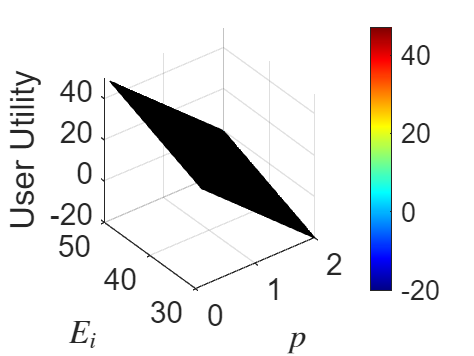

y = linspace(30,50,50);
x = linspace(0.1,2,50);
[X,Y] = meshgrid(x,y);
Z = Y./(exp(-5) + 1) - 25.*X;
colormap jet;
surf(X,Y,Z);
colorbar;
xlabel('$p$','Interpreter','latex');
ylabel('$E_i$','Interpreter','latex')
zlabel('User Utility')
set(gca, 'FontSize', 15) %调整x轴标签字体大小为16